# Question - 2 (PART- I)

% Clear workspace and command window
clear; clc; close all;
% For reproducibility
rng(27); 

## Given Data

N = 500; % Number of observations
Fs = 50; % Sampling frequency (Hz)

f1 = 10; % Frequency 1 (Hz)
f2 = 17; % Frequency 2 (Hz)

missing_percentage = 0.1; % Percentage of missing data (10%)

target_snr = 10; % Target Signal-to-Noise Ratio (SNR)

## Generate Data

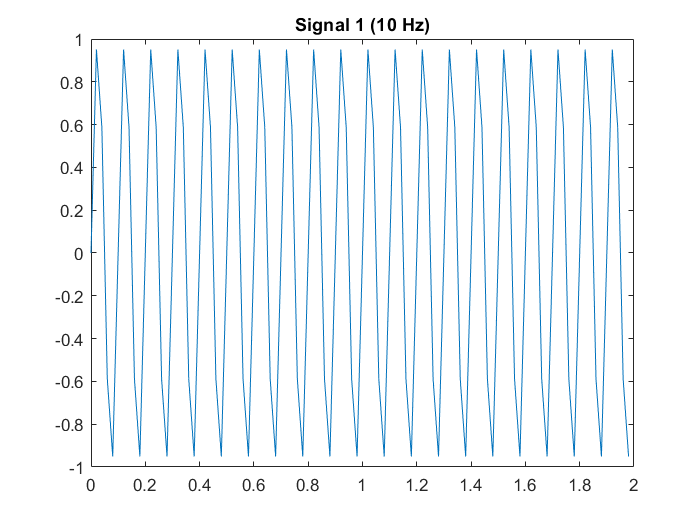

% Generate time vector
time = (0:N-1)'/Fs;

% Signal-1 10 Hz
signal1 = sin(2*pi*f1*time);
plot(time(1:100), signal1(1:100));
title("Signal 1 (10 Hz)");

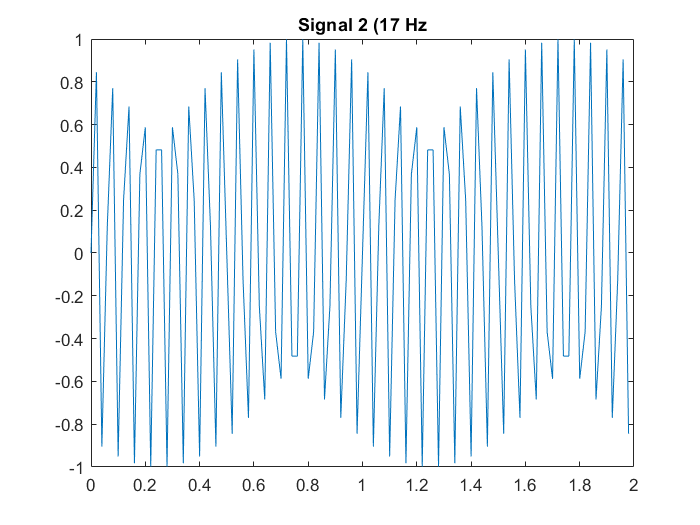

% Signal-2 17 Hz
signal2 = sin(2*pi*f2*time);
plot(time(1:100), signal2(1:100));
title("Signal 2 (17 Hz");

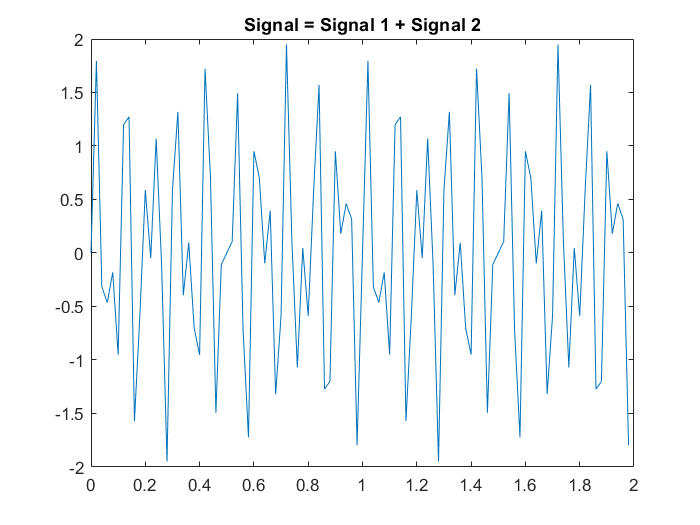

% Signal for analysis
signal =  signal1 + signal2;
plot(time(1:100), signal(1:100));
title("Signal = Signal 1 + Signal 2");

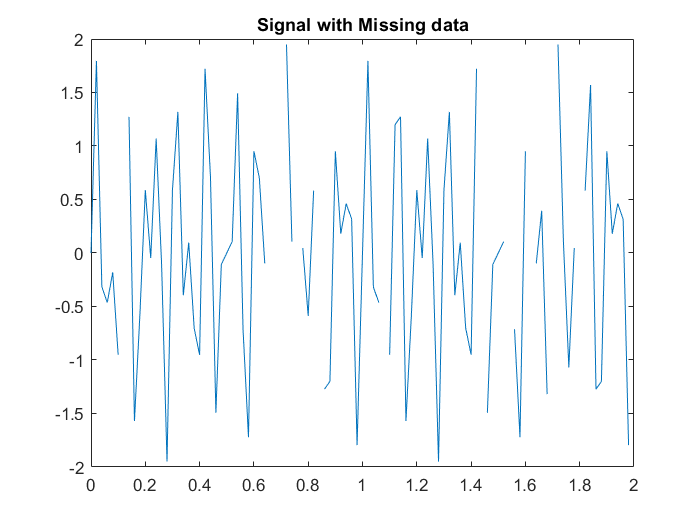

% Construct signal with Missing indices
missing_indices = sort(randperm(N, round(N*missing_percentage)));
missing_signal = signal;
missing_signal(missing_indices) = nan;
plot(time(1:100), missing_signal(1:100));
title("Signal with Missing data");

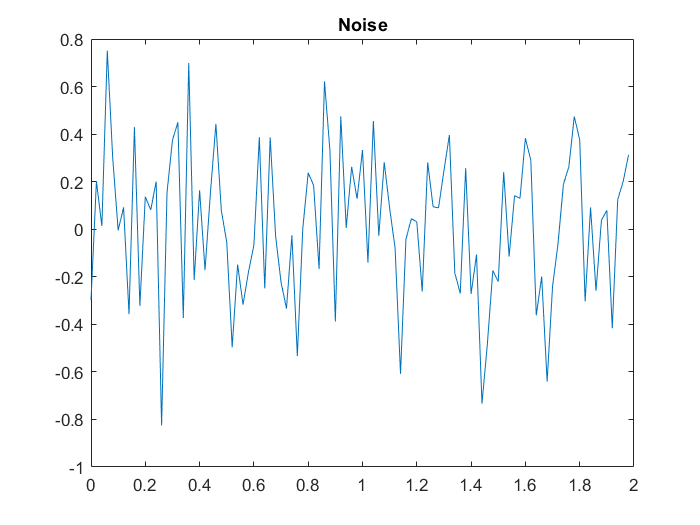

% Generate Noise Signal
signal_power = sum(signal.^2)/N;
noise_power = signal_power / (10^(target_snr/10));
noise = sqrt(noise_power) * randn(N, 1);
plot(time(1:100), noise(1:100))
title("Noise");

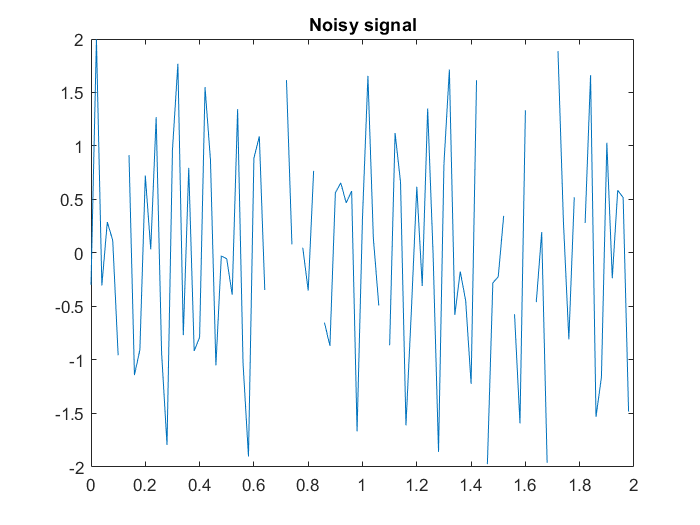

% Final signal with Noise and Missing data
noisy_signal = missing_signal + noise;
plot(time(1:100), noisy_signal(1:100));
title("Noisy signal");

**Data Generating Process - Summary**

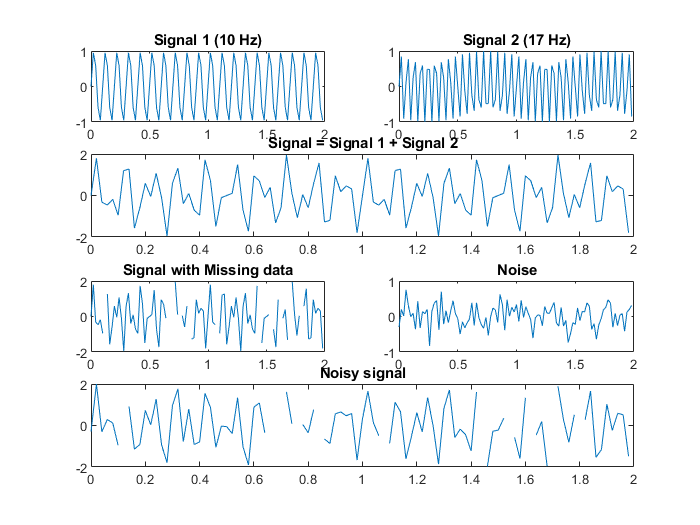

subplot(4,2,1);
plot(time(1:100), signal1(1:100));
title("Signal 1 (10 Hz)");

subplot(4,2,2);
plot(time(1:100), signal2(1:100));
title("Signal 2 (17 Hz)");

subplot(4,2,[3,4]);
plot(time(1:100), signal(1:100));
title("Signal = Signal 1 + Signal 2");

subplot(4,2,5);
plot(time(1:100), missing_signal(1:100));
title("Signal with Missing data");

subplot(4,2,6);
plot(time(1:100), noise(1:100))
title("Noise");

subplot(4,2,[7,8]);
plot(time(1:100), noisy_signal(1:100));
title("Noisy signal");

## Lomb-Scale Periodogram

learning_rate = 4e-3;
epochs = 400;
[F, P, C, A, B] = lomb_scale_periodogram(time, noisy_signal, learning_rate, epochs);

**Periodogram**

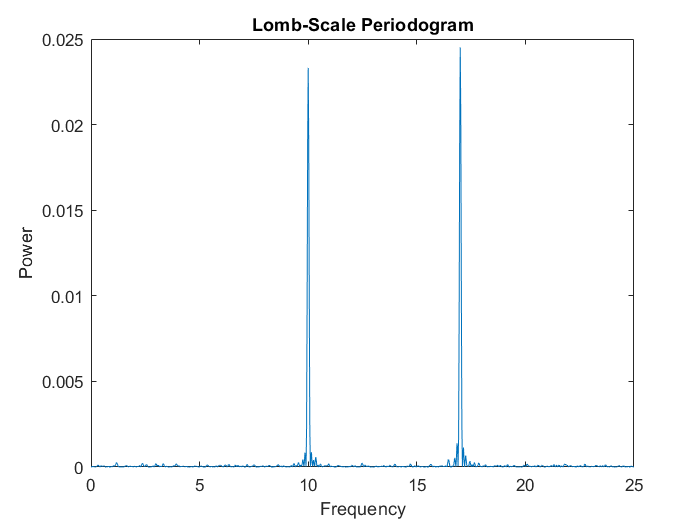

figure;
plot(F, P);
xlabel('Frequency');
ylabel('Power');
title('Lomb-Scale Periodogram');

**Cost History**

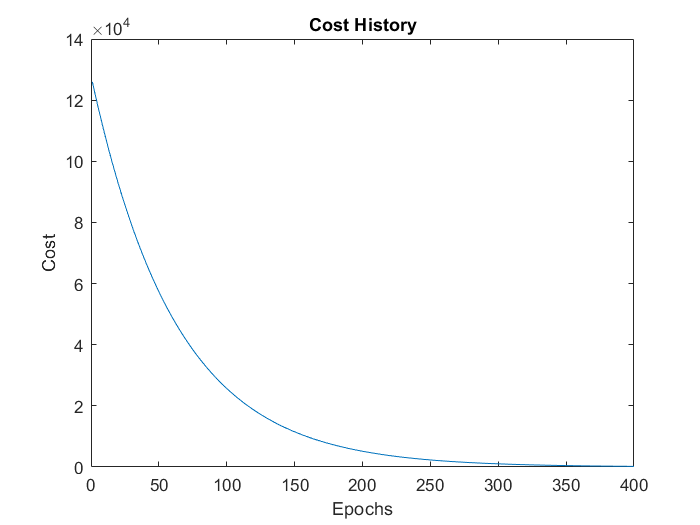

figure;
plot(1:epochs, C);
xlabel('Epochs');
ylabel('Cost');
title('Cost History');

## Predictions

reconstructed_signal = zeros(N, 1);
for i = 1:length(F)
    w = 2*pi*F(i);
    reconstructed_signal = reconstructed_signal + A(i)*cos(w*time) + B(i)*sin(w*time);
end

**Compare Signals**

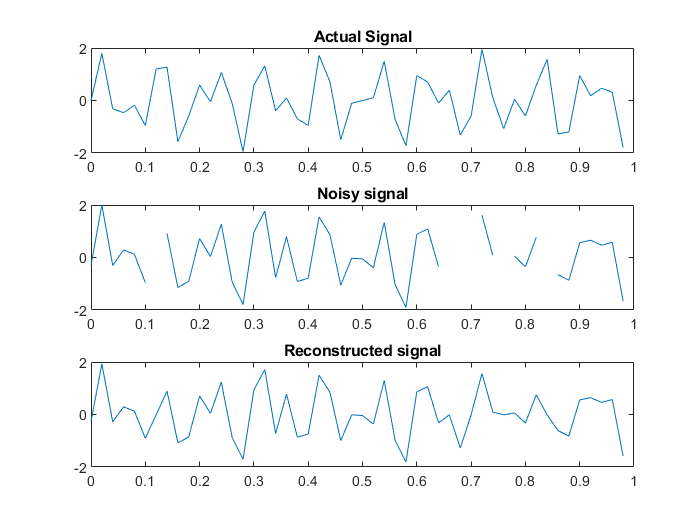

figure
subplot(3,1,1)
plot(time(1:50), signal(1:50));
title("Actual Signal");
subplot(3,1,2)
plot(time(1:50), noisy_signal(1:50));
title("Noisy signal");
subplot(3,1,3)
plot(time(1:50), reconstructed_signal(1:50));
title("Reconstructed signal");

**Model Prediction Comparison**

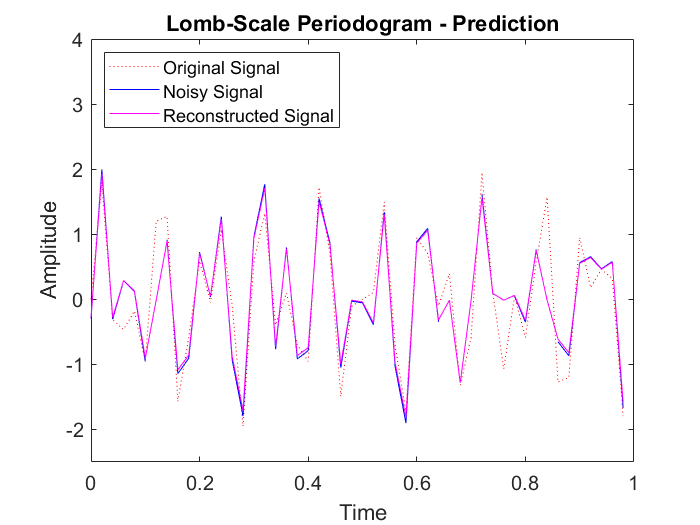

figure;
plot(time(1:50), signal(1:50), 'r:');
hold on;
plot(time(1:50), noisy_signal(1:50), 'b-');
hold on;
plot(time(1:50), reconstructed_signal(1:50), 'm-');
legend('Original Signal', 'Noisy Signal', 'Reconstructed Signal', 'Location', 'NorthWest');
xlabel('Time', 'FontSize', 14);
ylabel('Amplitude', 'FontSize', 14);
title('Lomb-Scale Periodogram - Prediction', 'FontSize', 14);
set(gca, 'FontSize', 12); % Set font size for axis labels and ticks
ylim([-2.5, 4]);
hold off;

## Metrics

[nmse1, mape1] = metrics(signal, reconstructed_signal);
[nmse2, mape2] = metrics(noisy_signal, reconstructed_signal);

**Original Signal vs Reconstructed Signal**

disp(table(nmse1, mape1, 'VariableNames', {'NMSE', 'MAPE'}));

     NMSE       MAPE 
    _______    ______

    0.61553    95.218



**Noisy Signal vs Reconstrcuted Signal**

disp(table(nmse2, mape2, 'VariableNames', {'NMSE', 'MAPE'}));

      NMSE        MAPE 
    _________    ______

    0.0027936    4.6254

